## Gold序列的仿真

@Copyright (c) zihan xing

使用gold序列对波形进行了设计

发射信号参数

clc;clear;close all;
fs = 4e3;
fc = 1.5e3;
Ts = 1/fs;
B = 200;    % 带宽（Hz）

### M序列信号

m = 5 ; l = 2^m-1 ; %阶数：5  
oct1 = 45 ;
gen  = [1 0 0 1 0 1] ;%生成多项式
seqs = gold(oct1,gen);%生成gold序列

Gold sequences


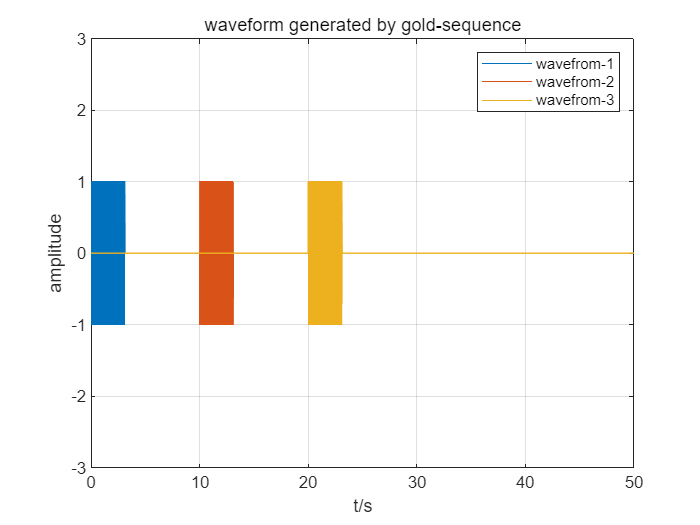


gold1 = seqs(1,:);
gold2 = seqs(15,:);
gold3 = seqs(30,:);


%2s的信号，31个二进制数
n = length(gold1);                   %相位变化点数31
%采用相位编码，设3.1s的CW信号
Tp = 3.1/n;                          %子脉冲长度Tp 3.1s
N_subpulse = round(Tp*fs);           %子脉冲采样点数
t_subpulse = 0 :1/fs:Tp-1/fs;        %时间序列，采样间隔为 1/fs

for kk = 1:n % 遍历每个变化点
    Nx1 = (kk-1)*N_subpulse+1;   % 当前跳频点的起始索引
    Nx11 = (kk)*N_subpulse;      % 当前跳频点的结束索引
    gold_pulse1(Nx1:Nx11) = exp(1i*(2*pi*fc*t_subpulse+pi*gold1(kk))); % 生成信号的复包络,3.1s
    gold_pulse2(Nx1:Nx11) = exp(1i*(2*pi*fc*t_subpulse+pi*gold2(kk))); % 生成信号的复包络,3.1s
    gold_pulse3(Nx1:Nx11) = exp(1i*(2*pi*fc*t_subpulse+pi*gold3(kk))); % 生成信号的复包络,3.1s
end    

%三个不同的匹配滤波器
matchedFilter1 = gold_pulse1;
matchedFilter2 = gold_pulse2;
matchedFilter3 = gold_pulse3;

TIME = 120;
n = round(3.1*fs);
paddled1 = [gold_pulse1 zeros(1,round(TIME*fs)-n)];                    %0~3.1s存在信号，时间尺度为100s
paddled2  = [zeros(1,10*fs) gold_pulse2 zeros(1,round((TIME-10)*fs)-n)];%10~13.1S存在信号
paddled3  = [zeros(1,20*fs) gold_pulse3 zeros(1,round((TIME-20)*fs)-n)];%20~23.1s存在信号


% 定义时间参数
t = (0:1/fs:TIME - 1/fs).'; % 时间向量，这里生成0到100秒的时间序列，采样间隔为1/fs
N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
figure
plot(t, real(paddled1));hold on;
plot(t, real(paddled2));hold on;
plot(t, real(paddled3));hold on;
xlabel('t/s');ylabel('amplitude');title('waveform generated by gold-sequence');
grid on;legend('wavefrom-1','wavefrom-2','wavefrom-3');
axis([0,50,-3,3]);


%计算三个波形的能量
E1 = sum(abs(gold_pulse1).^2);E2 = sum(abs(gold_pulse2).^2);E3 = sum(abs(gold_pulse3).^2);
disp(E1);disp(E2);disp(E3);

       12400

       12400

       12400



绘制模糊函数

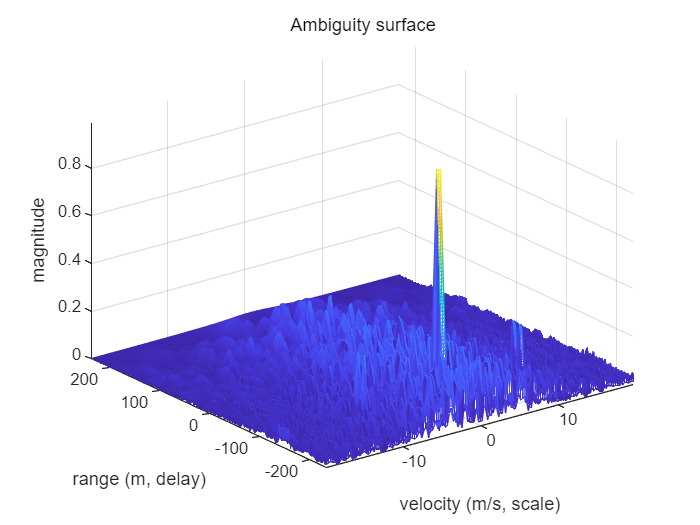

r=50;b=2;len=7;
c = 1500;                           %参考速度为1500
vmin = -20; vmax = 20;              %定义速度范围
velt= 0*c/(r*(b^len-1));            %速度为0，无多普勒 
etat = 1+(velt/c);                  %(1+v/c)用来计算经多普勒频移后的频率的比值
[pt,qt] = rat(etat);                %获取(1+v/c)的分子和分母
rs_bsig1 = resample(gold_pulse1,pt,qt);%对信号进行重采样
% delay
N = size(rs_bsig1,2);               %获取重采样的信号大小
delay = round((1000/c)*fs);         %TO DO:?????
obsvN = delay+N;                    %obsvN 总的观测的长度
s_n = [rs_bsig1 zeros(1,obsvN-N)];  %s_n 在原始信号后面补零
sig = s_n(1:obsvN-delay);           %截取的信号
bsig_no = [zeros(1,delay) sig];     %对sig添加延迟

clear obsvN sig N;

vel_del = c/(r*(b^len-1));          % vel_del 速度分辨率
vel = 0:vel_del:vmax;               
vel = [-vel(end:-1:2) vel];         % vel 速度范围：其中存储的是不同的速度，包括正负值
eta = 1+(vel/c);                    %获取(1+v/c)的分子和分母
[p,q]= rat(eta);                    

ambig1 = cell(1, length(vel));      %初始化两个cell数组
ambig2 = cell(1, length(vel));
ambig3 = cell(1, length(vel));

for i =1:length(vel)  % 遍历vel速度数组
    re_samp_bsig1 = resample(gold_pulse1,p(i),q(i));     % p>q expansion and p<q compression
    re_samp_bsig2 = resample(gold_pulse2,p(i),q(i));
    re_samp_bsig3 = resample(gold_pulse3,p(i),q(i));
    
    % --------在时域上进行相关处理----------------------------------- 
    if length(re_samp_bsig1)>length(bsig_no)   %如果重采样后的信号长度大于延迟信号，补零以匹配长度。
        na = length(re_samp_bsig1)-length(bsig_no);
        bsig_no= [bsig_no zeros(1,na+1)];
    end
    ambig1{i}=  abs(matchFilter(bsig_no,re_samp_bsig1,'none'));
    nl = length(bsig_no);
    ambigh1(1:(nl),i) =(ambig1{i});

    if length(re_samp_bsig2)>length(bsig_no)
        na = length(re_samp_bsig2)-length(bsig_no);
        bsig_no= [bsig_no zeros(1,na+1)];
    end     
    ambig2{i}=  abs(matchFilter(bsig_no,re_samp_bsig2,'none'));
    nl = length(bsig_no);
    ambigh2(1:(nl),i) =(ambig2{i});

    if length(re_samp_bsig3)>length(bsig_no)   %如果重采样后的信号长度大于延迟信号，补零以匹配长度。
        na = length(re_samp_bsig3)-length(bsig_no);
        bsig_no= [bsig_no zeros(1,na+1)];
    end
    ambig3{i}=  abs(matchFilter(bsig_no,re_samp_bsig3,'none'));
    nl = length(bsig_no);
    ambigh3(1:(nl),i) =(ambig3{i});


end

Max1= max(max(ambigh1));Max2= max(max(ambigh2));Max3= max(max(ambigh3));
A1=(abs(ambigh1 ./ Max1));A2=(abs(ambigh2 ./ Max2));A3 = (abs(ambigh3 ./ Max3));

%重采样模糊函数
%% resample the ambiguity funnction;
for i =1:length(vel)
    re_ambigh1(:,i)=resample(A1(:,i),1,6.);
    re_ambigh2(:,i)=resample(A2(:,i),1,6);
    re_ambigh3(:,i)=resample(A3(:,i),1,6);
end
A1=re_ambigh1;A2=re_ambigh2;A3=re_ambigh3;


figure;
N = length(A1); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A1);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;

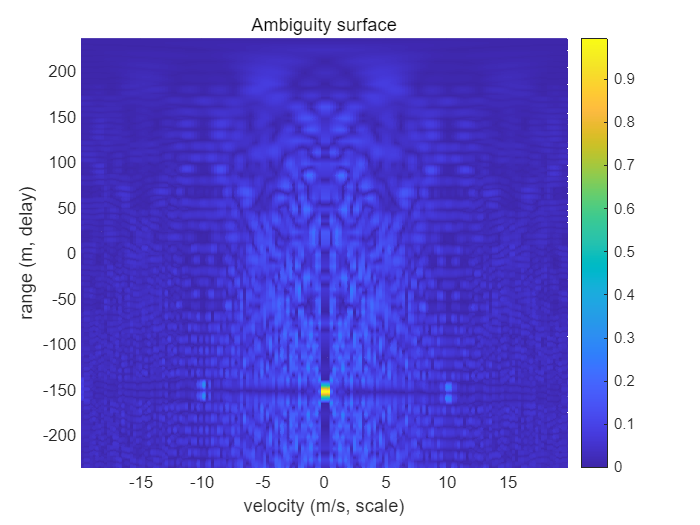

figure
N = length(A1); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A1);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;
view(0,90);colorbar;

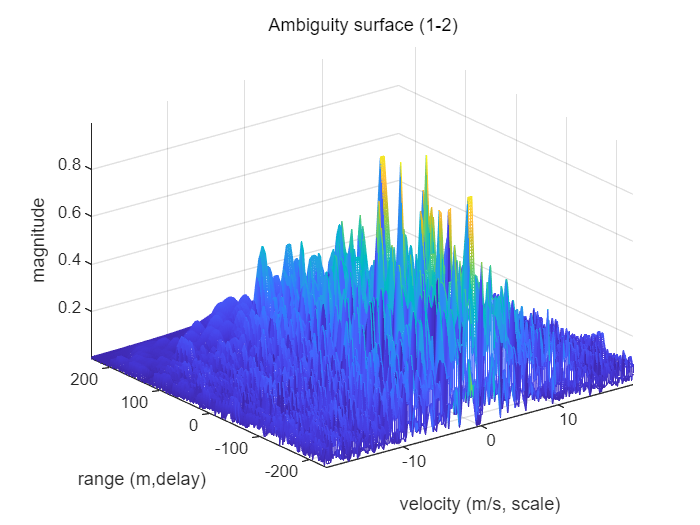


figure;
N = length(A2); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A2);
xlabel('velocity (m/s, scale)');ylabel('range (m,delay)'); zlabel('magnitude');
title('Ambiguity surface (1-2)'); axis tight;

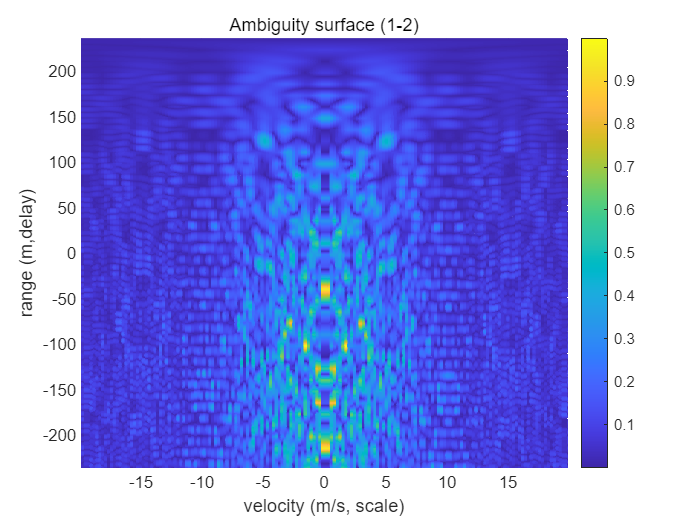

figure
N = length(A2); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A2);
xlabel('velocity (m/s, scale)');ylabel('range (m,delay)'); zlabel('magnitude');
title('Ambiguity surface (1-2)'); axis tight;
view(0,90);colorbar;

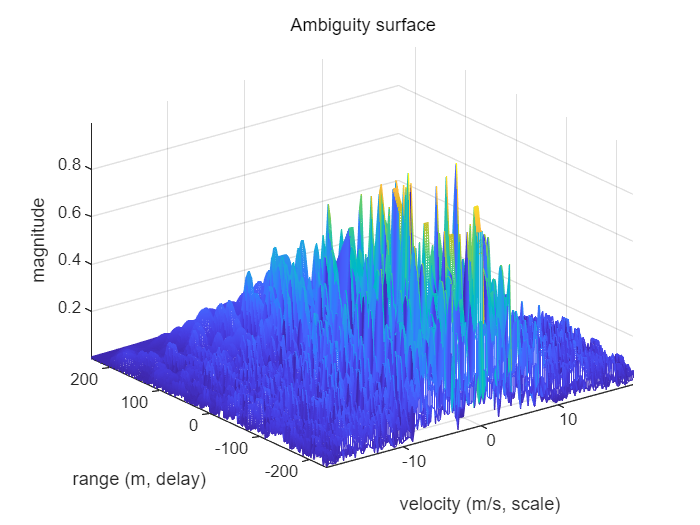

figure;
N = length(A3); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A3);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;

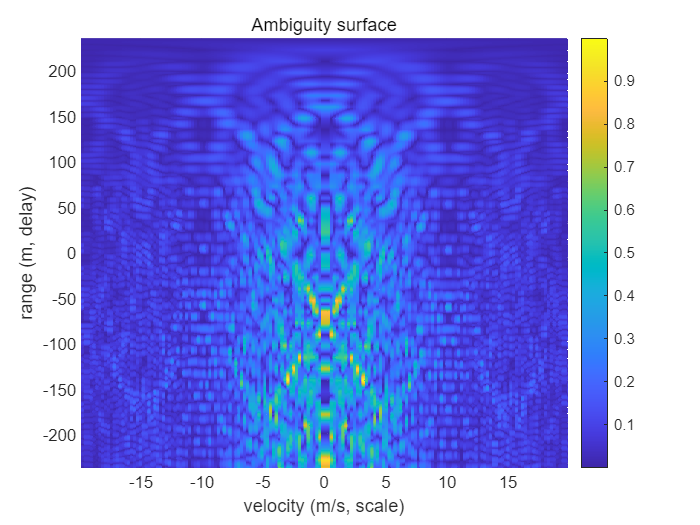

figure
N = length(A3); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A3);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;
view(0,90);colorbar;

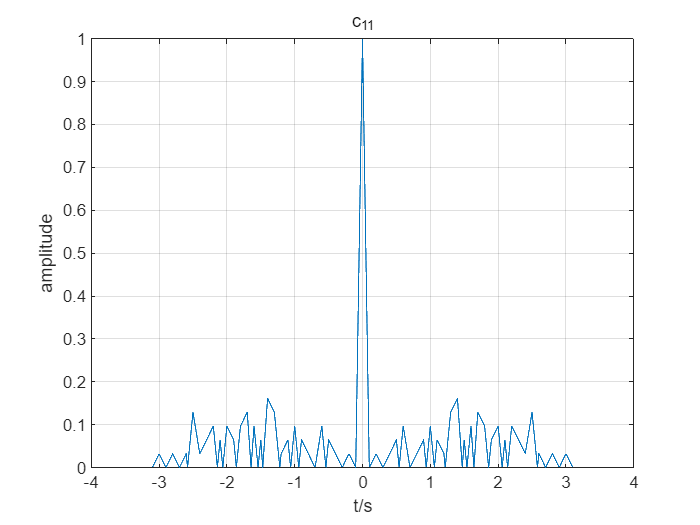

%计算相关函数
[c11,lags] = xcorr(gold_pulse1 ,gold_pulse1);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
c11 = c11./length(gold_pulse1);
figure
plot(lags*(1/fs),abs(c11));grid on;
xlabel('t/s');ylabel('amplitude');
title('c_{11}');ylim([0,1]);

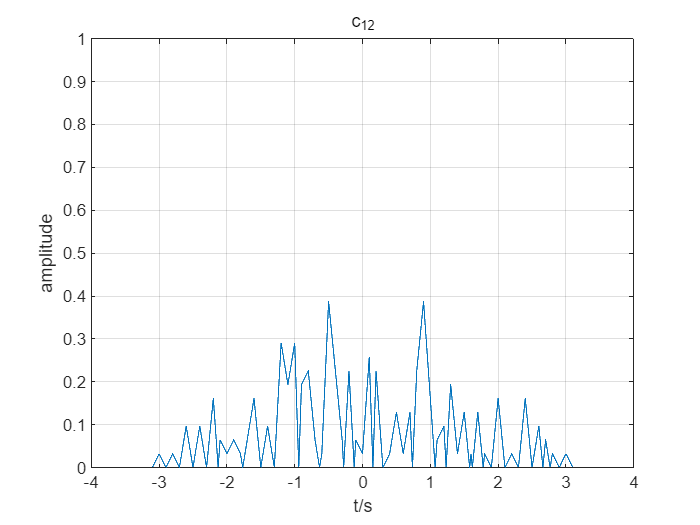


[c12,lags] = xcorr(gold_pulse1 ,gold_pulse2);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
c12 = c12./length(gold_pulse1);
figure
plot(lags*(1/fs),abs(c12));grid on;title('correlation-c12');ylim([0,1]);
xlabel('t/s');ylabel('amplitude');
title('c_{12}');ylim([0,1]);

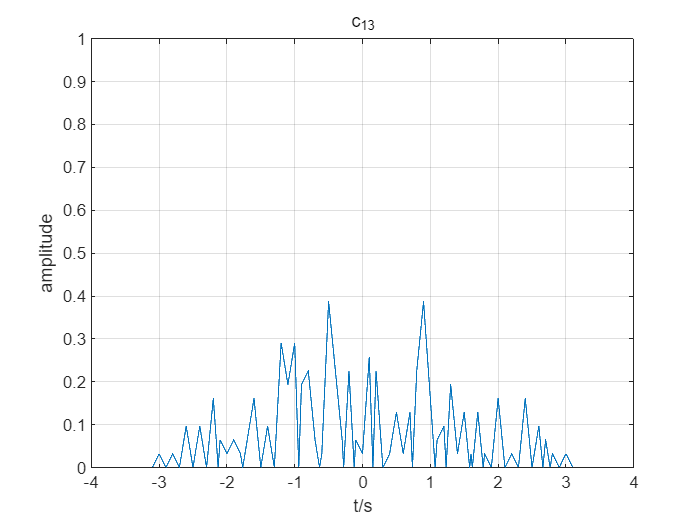


[c13,lags] = xcorr(gold_pulse1 ,gold_pulse2);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
c13 = c13./length(gold_pulse1);
figure
plot(lags*(1/fs),abs(c13));grid on;
title('c_{13}');ylim([0,1]);
xlabel('t/s');ylabel('amplitude');

## 信道

###  声速梯度


figure; 
bellhop Data\MunkB_Coh;
plotssp('Data\MunkB_Coh');

根据声速梯度图，当深度为200m时，声速为1530m/s

###     传播损失

%计算传播损失

bellhop('Data\MunkB_Coh');
figure
plotshd('Data\MunkB_Coh.shd');

直达区：

- 接收点：深度3000m，距离12000

- 发射点：深度200m

声影区：

- 接收点：深度300m，距离50000

- 发射点：深度200m

第一会聚区：

- 接收点：深度300m，距离58954m

- 发射点：深度200m

### 信道的脉冲响应

bellhop计算脉冲响应

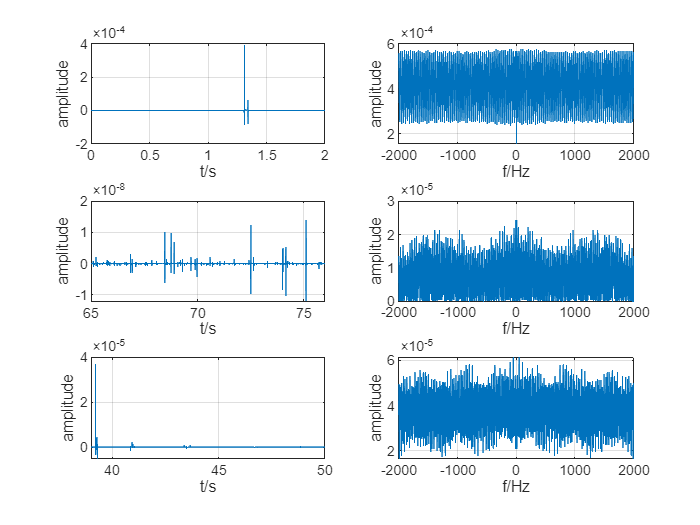

bellhop('Data\direct_Arr');                %直达区
[ Arr1, ~ ] = read_arrivals_asc( 'Data\direct_Arr.arr' );

bellhop('Data\shadow_Arr');                %声影区
[ Arr2, ~ ] = read_arrivals_asc( 'Data\shadow_Arr.arr' );

bellhop('Data\convergence1_Arr');                %第一会聚区
[ Arr3, ~ ] = read_arrivals_asc( 'Data\convergence1_Arr.arr' );


t = 0:1/fs:TIME - 1/fs; % 时间向量，这里生成0到100秒的时间序列，采样间隔为1/fs

%获取脉冲响应
%fs：采样频率，时间长度100s
IR1 = get_IR(Arr1, fs, TIME);%IR1：直达区脉冲响应
TF1 = fftshift(fft(IR1)).';

IR2 = get_IR(Arr2, fs, TIME);%IR2：声影区脉冲响应
TF2 = fftshift(fft(IR2)).';

IR3 = get_IR(Arr3, fs, TIME);%IR3：第一会聚区脉冲响应
TF3 = fftshift(fft(IR3)).';

N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
figure
subplot(3,2,1)
plot(t,IR1);grid on;xlim([0,2]);
xlabel('t/s');ylabel('amplitude');

subplot(3,2,2)
plot(f,abs(TF1));grid on;
xlabel('f/Hz');ylabel('amplitude');

subplot(3,2,3)
plot(t,IR2);grid on;xlim([65,76]);
xlabel('t/s');ylabel('amplitude');

subplot(3,2,4)

plot(f,abs(TF2));grid on;
xlabel('f/Hz');ylabel('amplitude');

subplot(3,2,5)
plot(t,IR3);grid on;xlim([39,50]);
xlabel('t/s');ylabel('amplitude');

subplot(3,2,6)
plot(f,abs(TF3));grid on;
xlabel('f/Hz');ylabel('amplitude');

工具箱绘制脉冲响应

plotarr('Data\direct_Arr.arr',1,1,1);
plotarr('Data\shadow_Arr.arr',1,1,1);

plotarr('Data\convergence1_Arr.arr',1,1,1);
clear Arr1 Arr2 Arr3;

## 仿真亮点模型

R为鱼雷与潜艇距离,即鱼雷与代表艇尾的亮点距离;0为照射角;表示该亮点与艇艉的距离

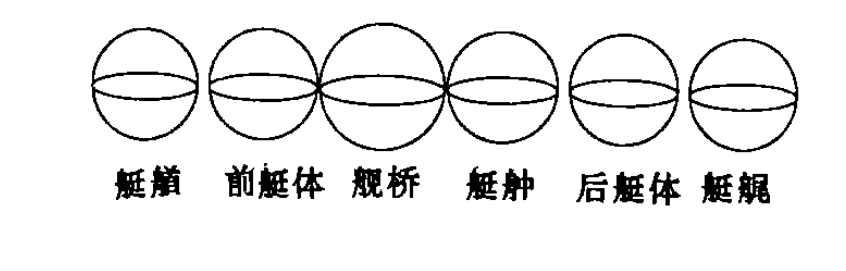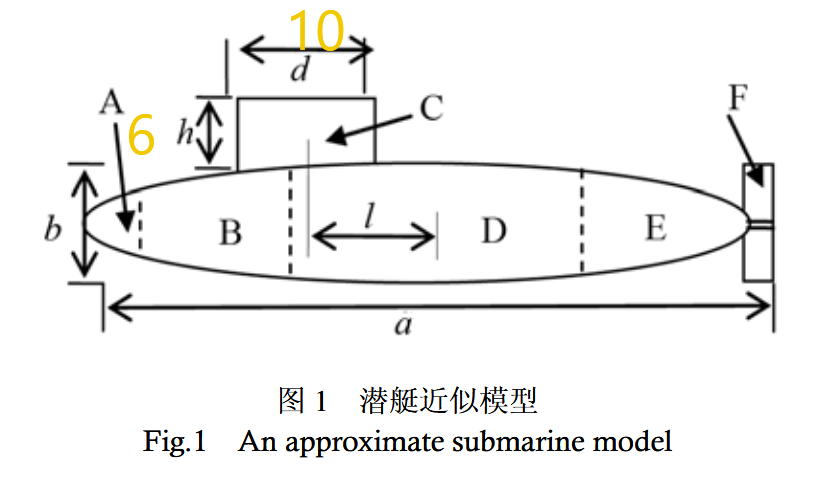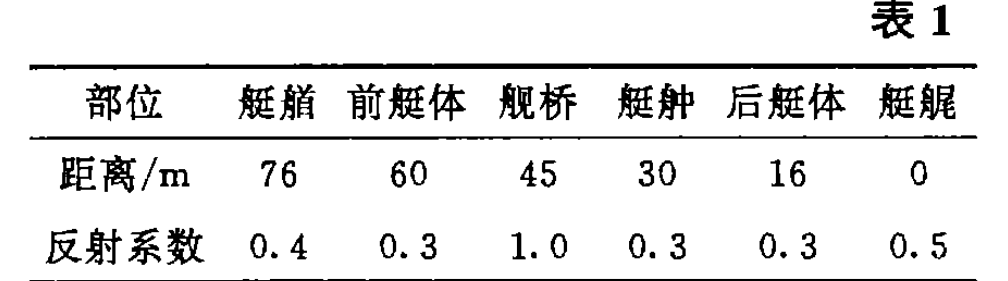

亮点模型各个亮点的时延：$\tau_i = \frac{2\sqrt{(L_icos\theta)^2+(L_isin\theta)^2}}{c}$

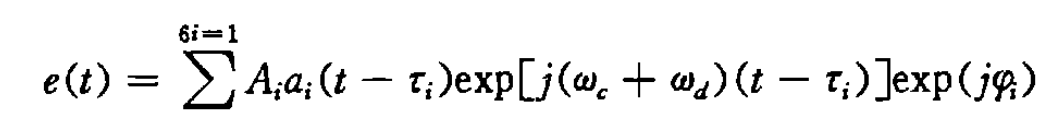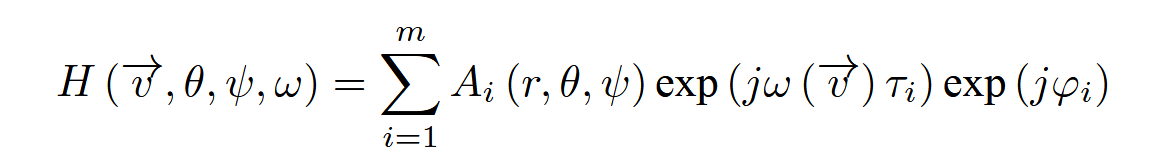

L = [76,   60,     45,   30,   16,   0]; 
b = [0.4, 0.3, 1.0, 0.3, 0.3, 0.5];% 定义距离和反射系数
r = [7,7,8,7,7,7];

c = 1530;    %深度1000m 声速1500m/s
N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
theta = 90;
phi = pi;


TF_highlight = get_highlight_TF(c,fs,N,theta,L,b,r).';


绘制亮点的转移函数和脉冲响应

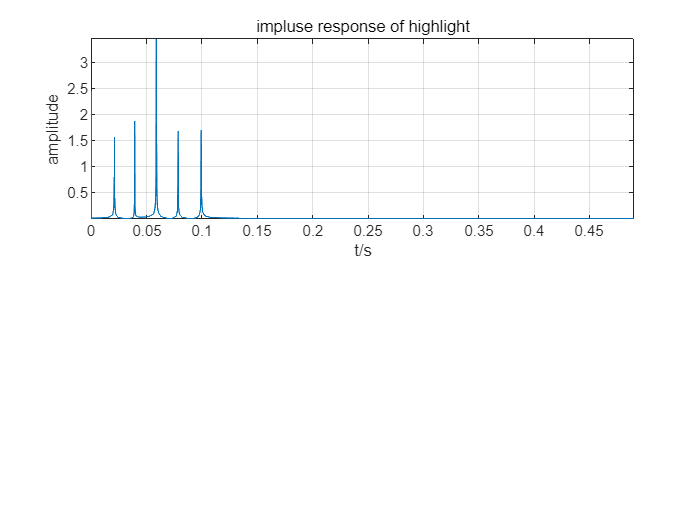

figure
% subplot(2,1,2);
% plot(f,abs(TF_highlight));xlabel('f/Hz');ylabel('幅度');grid on;title('亮点模型转移函数');
% axis(-fs/2,fs/2,0,inf);
IR_Highlight = ifft(fftshift(TF_highlight));

subplot(2,1,1);
time = 0.49;
plot(t,abs(IR_Highlight));xlabel('t/s');ylabel('amplitude');grid on;title('impluse response of highlight');
axis([0,time,-inf,inf]);
clear IR_Highlight;

s1_f = fftshift(fft(paddled1.')).*TF1.*TF_highlight;%经过信道到达目标

s2_f = fftshift(fft(paddled1).').*TF2.*TF_highlight;%目标的转移函数

s3_f = fftshift(fft(paddled1).').*TF3.*TF_highlight;%目标的转移函数

clear P1 P2 P3;
clear  TF_highlight L b R;

## 信号返回发射点：

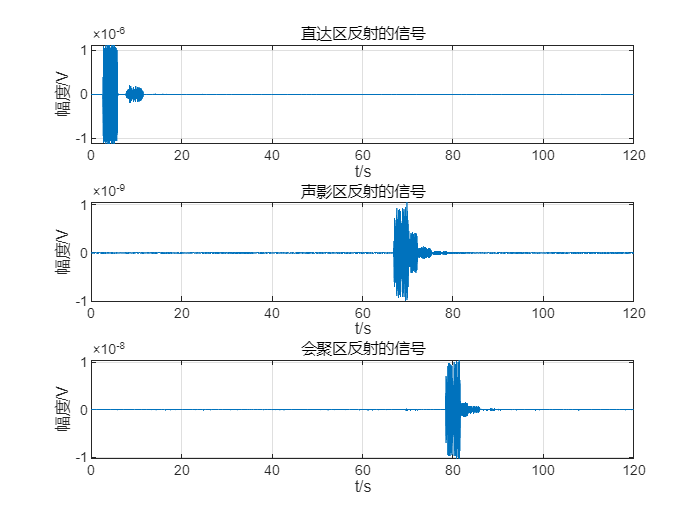

temp = s1_f.*TF1;
s1 = ifft(fftshift(temp));%交换变量

temp = s2_f.*TF2;
s2 = ifft(fftshift(temp));%交换变量

temp = s3_f.*TF3;
s3 = ifft(fftshift(temp));%交换变量

figure
subplot(3,1,1)
plot(t,real(s1));xlabel('t/s');ylabel('幅度/V');grid on;
title(sprintf('直达区反射的信号', theta));
subplot(3,1,2)
plot(t,real(s2));xlabel('t/s');ylabel('幅度/V');grid on;
title(sprintf('声影区反射的信号', theta));

subplot(3,1,3)
plot(t,real(s3));xlabel('t/s');ylabel('幅度/V');grid on;
title(sprintf('会聚区反射的信号', theta));

## 检测脉冲

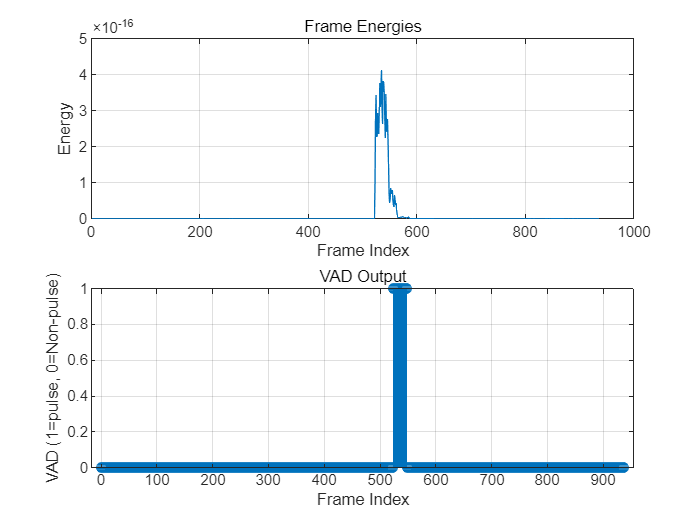

frame_length = 1024;       % 帧长（样本点数）
frame_shift = 512;         % 帧移（样本点数）
threshold = 1e-16;         % 能量阈值（根据实验调整）

num_frames = floor(length(s2 ) / frame_shift) - 1;  % 计算帧的数量

% 计算每帧的能量
frame_energies = zeros(num_frames, 1);
for i = 1:num_frames
    start_index = (i - 1) * frame_shift + 1;
    end_index = start_index + frame_length - 1;
    frame = s2(start_index:end_index);       % 提取当前帧
    frame_energies(i) = sum(abs(frame).^2);  % 计算帧的能量
end

% 判断语音活动
vad_output = frame_energies > threshold;  % 如果能量大于阈值，则为语音活动

% 可视化每帧的能量
figure;
subplot(2,1,1);
plot(frame_energies);grid on;
title('Frame Energies');xlabel('Frame Index');ylabel('Energy');

% 可视化VAD输出结果
subplot(2,1,2);
stem(vad_output);
title('VAD Output');grid on;

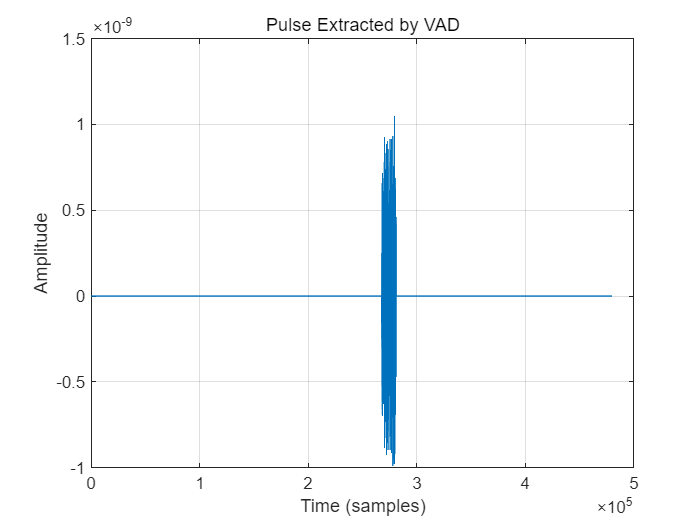

xlabel('Frame Index');ylabel('VAD (1=pulse, 0=Non-pulse)');

% 提取语音信号
vad_signal = zeros(size(s2));  % 初始化信号
for i = 1:num_frames
    start_index = (i - 1) * frame_shift + 1;
    end_index = start_index + frame_length - 1;
    if vad_output(i) == 1  % 如果是语音活动
        vad_signal(start_index:end_index) = s2(start_index:end_index);
    end
end

% 可视化提取的语音信号
figure;
plot(real(vad_signal));grid on;
title('Pulse Extracted by VAD');

xlabel('Time (samples)');ylabel('Amplitude');

E2_beamformed = sum(abs(vad_signal).^2);

   3.7279e-15



disp(E2_beamformed);
TL = 10*log10(E2/E2_beamformed);

经过声影区传播损失为 185.2195dB

fprintf('经过声影区传播损失为 %.4fdB',TL);

## 波束形成

接收到的信号波束形成

考虑阵列情况

d = 1;                  % 阵元间距（10m长的线阵，共10个元素）
eleNum = 10;                 % 阵元数量
angles = -90:10:90;     % 角度范围 -90° 到 90°
alpha = 60;             %阵列的接收角度（0°~180°）

%% 仿真阵元域数据
t = 0:1/fs:TIME-1/fs; % 总时间向量

beamformed_signals_time_domain1 = beamform(s1.',t,fs,d,c,eleNum,angles,alpha);
beamformed_signals_time_domain2 = beamform(s2.',t,fs,d,c,eleNum,angles,alpha);
beamformed_signals_time_domain3 = beamform(s3.',t,fs,d,c,eleNum,angles,alpha);


## 波束处理后的接收信号

波束角度60°

s1_beam60 = beamformed_signals_time_domain1(7,:);
s2_beam60 = beamformed_signals_time_domain2(7,:);
s3_beam60 = beamformed_signals_time_domain3(7,:);
clear beamformed_signals_time_domain1 beamformed_signals_time_domain2 beamformed_signals_time_domain3;
clear s1 s2 s3;
figure
subplot(3,1,1)
plot(t,real(s1_beam60));xlabel('t/s');ylabel('Am');grid on;
subplot(3,1,2)
plot(t,real(s2_beam60));xlabel('t/s');ylabel('Am');grid on;
subplot(3,1,3)
plot(t,real(s3_beam60));xlabel('t/s');ylabel('Am');grid on;

## 匹配滤波

时域信号


[r1,lags] = xcorr(s1_beam60 ,matchedFilter1);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
r1 = r1(idx:end);
lags = lags(idx:end);

[r2,~] = xcorr(s2_beam60 ,matchedFilter1);
r2 = r2(idx:end);

[r3,~] = xcorr(s3_beam60 ,matchedFilter1);
r3 = r3(idx:end);

clear  temp;

figure
subplot(3,1,1)
plot(lags*(1/fs),real(r1));xlabel('t/s');ylabel('Am');grid on;title('直达区');
subplot(3,1,2)
plot(lags*(1/fs),real(r2));xlabel('t/s');ylabel('Am');grid on;title('声影区');
subplot(3,1,3)
plot(lags*(1/fs),real(r3));xlabel('t/s');ylabel('Am');grid on;title('会聚区');
t = 0:1/fs:TIME-1/fs;
s1 = gather(r1);
s2 = gather(r2);
s3 = gather(r3);
clear r1 r2 r3;
s1 = gather(s1_beam60);
s2 = gather(s2_beam60);
s3 = gather(s3_beam60);

时频

audiowrite('m_cw_pulse_s1.wav',real(s1)./max(abs(s1)),fs);
audiowrite('m_cw_pulse_s2.wav',real(s2)./max(abs(s2)),fs);
audiowrite('m_cw_pulse_s3.wav',real(s3)./max(abs(s3)),fs);